% Αρχή χρονομέτρου
tic

% Φόρτωση και Επισκόπηση του Dataset
disp("Φόρτωση του dataset.")

Φόρτωση του dataset.


T = readtable('seven_wonders_reviews.xlsx', 'TextType', 'string');
head(T)

          user          rating                                                                                                                                                                                                                                                                                                                                                                                                         comment                                                                                                                                                                                                                                                                                                                                                                                                     
    ________________    ______    _____________________________________________________

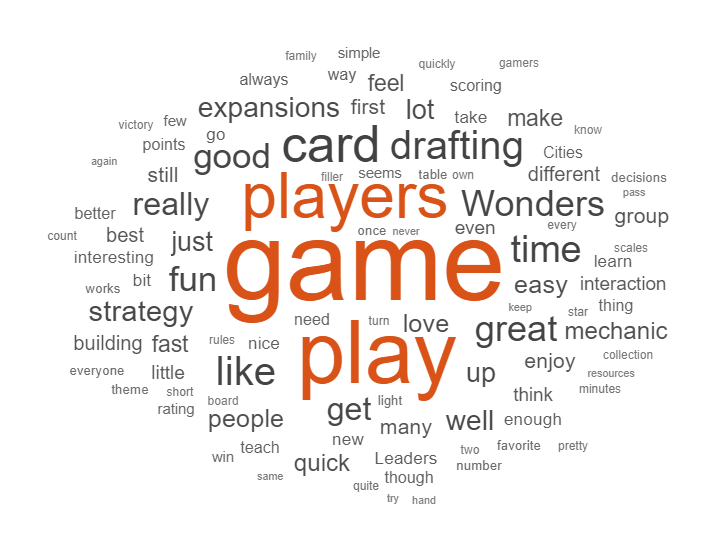


new_reviews = [
    "7 Wonders is an exceptional game that brilliantly captures the thrill of civilization building. The drafting mechanic keeps all players engaged, and the diverse strategies make each game unique. With beautiful artwork and well-designed components, it’s a visual treat as well. It’s a perfect choice for both casual and serious gamers looking to have a great time together."
    "While 7 Wonders has its fans, I found it somewhat underwhelming. The game can feel a bit repetitive after a few plays, as the strategies can become predictable. Additionally, the scoring system can be confusing for new players, leading to a frustrating experience. It’s not the engaging civilization-building game I hoped it would be."
    "7 Wonders is a game with great potential, showcasing fantastic artwork and an engaging premise. The drafting mechanism is fun and encourages interaction among players. However, I felt that the learning curve can be steep for newcomers, which might hinder the enjoyment for some. Overall, it’s a solid game with its highs and lows, making it worth a try for those who appreciate strategic gameplay."];

categoricalRatings = strings(size(T.rating));
categoricalRatings(T.rating >= 1 & T.rating <= 5) = "Χαμηλές Βαθμολογίες";
categoricalRatings(T.rating >= 5.1 & T.rating <= 7.9) = "Μέτριες Βαθμολογίες";
categoricalRatings(T.rating >= 8 & T.rating <= 10) = "Υψηλές Βαθμολογίες";
categoricalRatings = categorical(categoricalRatings, ...
    ["Χαμηλές Βαθμολογίες", "Μέτριες Βαθμολογίες", "Υψηλές Βαθμολογίες"]);

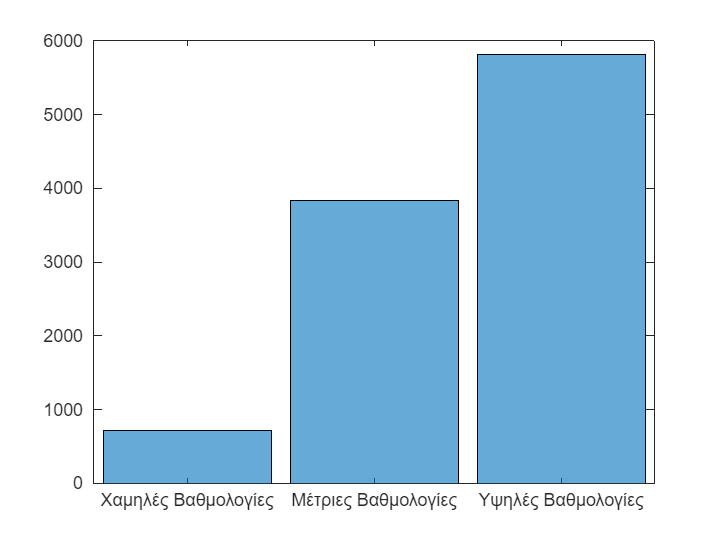

% Οπτικοποίηση της κατανομής των βαθμολογιών
figure(1)
histogram(categoricalRatings)

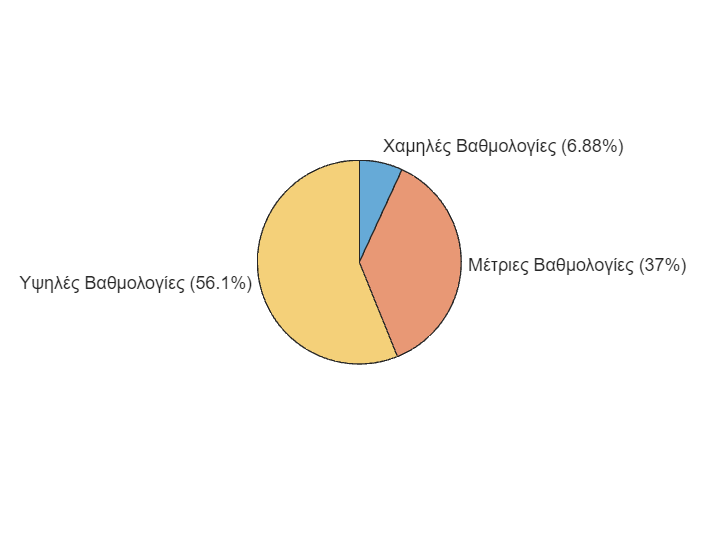

figure(2)
piechart(categoricalRatings)

% Προεπεξεργασία Σχολίων και Δημιουργία Αρχικού Word Cloud

disp("Εκτέλεση προεπεξεργασίας για την απομάκρυνση θορύβου και δημιουργία ενός αρχικού word cloud για τα σχόλια.")

Εκτέλεση προεπεξεργασίας για την απομάκρυνση θορύβου και δημιουργία ενός αρχικού word cloud για τα σχόλια.


[preprocessedText] = text_preprocessing(T.comment);

% Προβολή Λεπτομερειών Τοκενς και Εμφάνιση Word Cloud
disp("Λεπτομέρειες tokens των επεξεργασμένων σχολίων:")

Λεπτομέρειες tokens των επεξεργασμένων σχολίων:


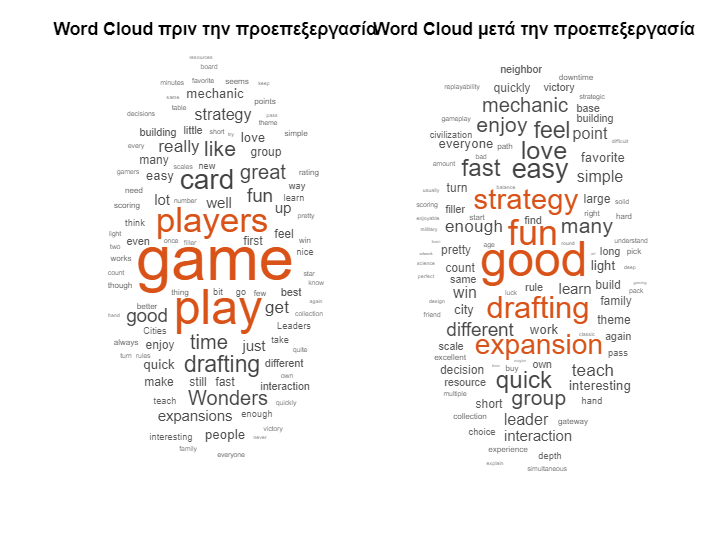

tokenDetails(preprocessedText);
figure
subplot(1,2,1);
wordcloud(T.comment);
title("Word Cloud πριν την προεπεξεργασία")
subplot(1,2,2);
wordcloud(preprocessedText);
title("Word Cloud μετά την προεπεξεργασία")

% Εκτύπωση Word Clouds για κάθε κατηγορία βαθμολόγησης
disp("Εκτύπωση Word Clouds για κάθε κατηγορία βαθμολόγησης.")
[toplow, topmed, tophigh] = multiword_phrases(T);
disp("Top 10 φράσεις στις χαμηλές βαθμολογίες.")
disp(toplow)
disp("Top 10 φράσεις στις μέτριες βαθμολογίες.")
disp(topmed)
disp("Top 10 φράσεις στις υψηλές βαθμολογίες.")
disp(tophigh)

## TEXT CLASSIFICATION

% Χρήση ενός Απλού Εποπτευόμενου Ταξινομητή για Εκτίμηση Βαθμολογίας
disp("Χρήση ενός απλού εποπτευόμενου ταξινομητή για εκτίμηση της βαθμολογίας νέων κριτικών.")
new_reviews = [
    "7 Wonders is an exceptional game that brilliantly captures the thrill of civilization building. The drafting mechanic keeps all players engaged, and the diverse strategies make each game unique. With beautiful artwork and well-designed components, it’s a visual treat as well. It’s a perfect choice for both casual and serious gamers looking to have a great time together."
    "While 7 Wonders has its fans, I found it somewhat underwhelming. The game can feel a bit repetitive after a few plays, as the strategies can become predictable. Additionally, the scoring system can be confusing for new players, leading to a frustrating experience. It’s not the engaging civilization-building game I hoped it would be."
    "7 Wonders is not a great game. I felt that the learning curve can be steep for newcomers, which might hinder the enjoyment for some. Overall, in my opinion, it is not a game for those who don't want to think very much."];
[acc_SC] = simple_SC(T, new_reviews);

% Εκτέλεση ταξινόμησης με embeddings για Hold-Out και Cross-Validation
disp("Εκτέλεση ταξινόμησης με embeddings σε Hold-Out και Cross-Validation για την εύρεση του καλύτερου ταξινομητή.")
[holdoutAccuracies, crossvalAccuracies] = classification_with_embeddings(T);

% Ταξινομητής με Embeddings Εγγράφων
disp("Χρήση ταξινομητή με embeddings εγγράφων για καλύτερη ανάλυση των σχολίων.")
[acc_DE_linear, acc_DE_rbf, categoryCounts] = doc_embeddings(T);

## LDA - TOPIC MODELING 

% Προσδιορισμός του βέλτιστου solver για το LDA
disp("Προσδιορισμός του βέλτιστου solver για το LDA με χρήση της συνάρτησης lda_solvers_comp.")
lda_solvers_comp(T.comment);

% Προσδιορισμός του βέλτιστου αριθμού θεμάτων για το LDA με Hold Out
disp("Προσδιορισμός του βέλτιστου αριθμού θεμάτων για το LDA με χρήση της συνάρτησης nof_topics_lda.")
[results] = nof_topics_lda(T.comment);

% Προσδιορισμός του βέλτιστου αριθμού θεμάτων για το LDA με Cross Validation
disp("Προσδιορισμός του βέλτιστου αριθμού θεμάτων για το LDA με χρήση της συνάρτησης nof_topics_lda_cv.")
[results_cv] = nof_topics_lda_cv(T.comment);

% Προβολή Πιθανότητας Θεμάτων για Νέα Σχόλια σε LDA
disp("Ανάλυση θεμάτων για νέα σχόλια χρησιμοποιώντας το εκπαιδευμένο μοντέλο LDA.")
new_reviews = [
    "7 Wonders is an exceptional game that brilliantly captures the thrill of civilization building. The drafting mechanic keeps all players engaged, and the diverse strategies make each game unique. With beautiful artwork and well-designed components, it’s a visual treat as well. It’s a perfect choice for both casual and serious gamers looking to have a great time together."
    "While 7 Wonders has its fans, I found it somewhat underwhelming. The game can feel a bit repetitive after a few plays, as the strategies can become predictable. Additionally, the scoring system can be confusing for new players, leading to a frustrating experience. It’s not the engaging civilization-building game I hoped it would be."
    "7 Wonders is a game with great potential, showcasing fantastic artwork and an engaging premise. The drafting mechanism is fun and encourages interaction among players. However, I felt that the learning curve can be steep for newcomers, which might hinder the enjoyment for some. Overall, it’s a solid game with its highs and lows, making it worth a try for those who appreciate strategic gameplay."];
[tbl,top] = my_lda(T.comment, new_reviews);
disp("Οι κορυφαίες λέξεις ανά θέμα για τις νέες κριτικές έχουν ως εξής:")
disp(top)

## BERT - TRANSFORMER TEXT CLASSIFICATION

% Εκπαίδευση Tiny BERT για ταξινόμηση
[tiny_bert_accuracy, tiny_bert_precision, tiny_bert_recall, tiny_bert_f1_score] = tiny_bert(T);

% Εκπαίδευση Mini BERT για ταξινόμηση
[mini_bert_accuracy, mini_bert_precision, mini_bert_recall, mini_bert_f1_score] = mini_bert(T);

% Εκπαίδευση Small BERT για ταξινόμηση
[small_bert_accuracy, small_bert_precision, small_bert_recall, small_bert_f1_score] = small_bert(T);

## SENTIMENT ANALYSIS

[compoundScores, tbl] = darth_vader(T.comment);

% Δημιουργία, εκπαίδευση και δοκιμή ενός VADER μοντέλου με ειδικά προσαρμοσμένο λεξικό
[compoundScores, lexiconTable, testDataResults] = darth_vader_train_test(T);

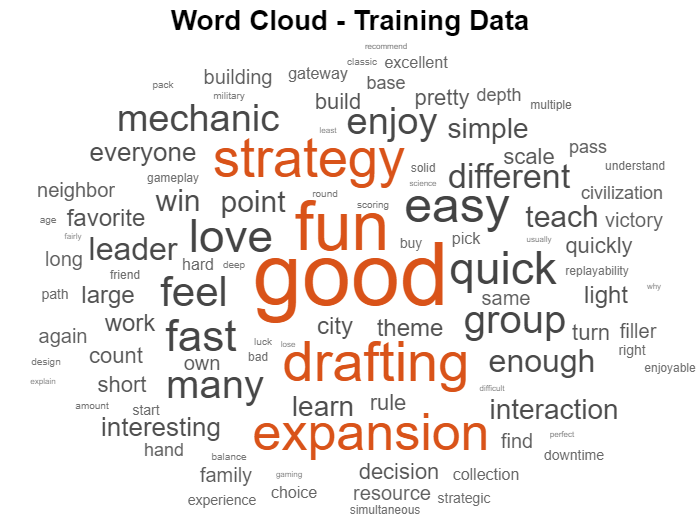

Training: 100% Loss: 2.36851  Remaining time: 0 hours 0 minutes.


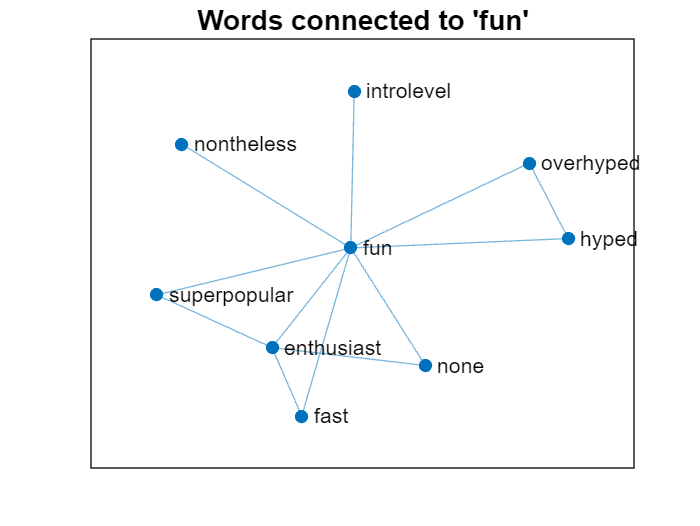

         Token          SentimentScore
    ________________    ______________

    "innovative"                  4   
    "creative"                    4   
    "fun"                    3.9071   
    "enjoy"                  3.9071   
    "interesting"             3.907   
    "engaging"               3.9062   
    "rewarding"              3.9062   
    "exciting"               3.9062   
    "favorite"               3.9058   
    "fantastic"              3.9057   
    "excellent"              3.9056   
    "amazing"                3.9056   
    "love"                   3.9056   
    "great"                  3.9056   
    "best"                   3.9056   
    "awesome"                3.9056   
    "strategic"              3.9056   
    "good"                   3.8212   
    "strong"                 3.7637   
    "token"                 0.54593   
    "magic"                  0.4285   
    "none"                  0.3395

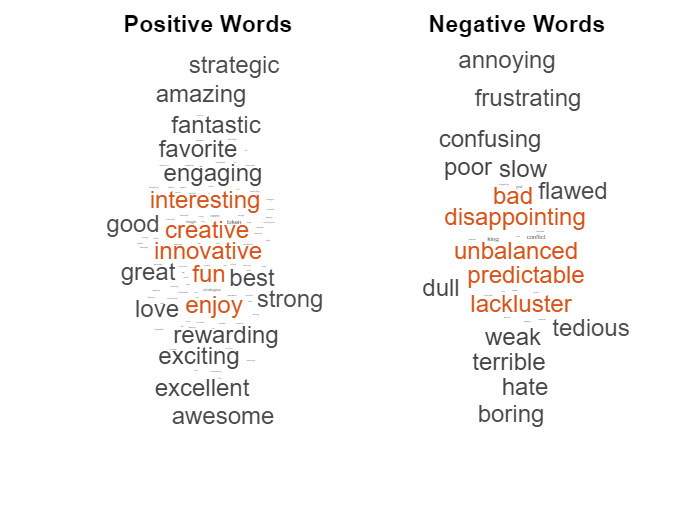

Processed comment 1/2000 via GPT‑4
Processed comment 2/2000 via GPT‑4
Processed comment 3/2000 via GPT‑4
Processed comment 4/2000 via GPT‑4
Processed comment 5/2000 via GPT‑4
Processed comment 6/2000 via GPT‑4
Processed comment 7/2000 via GPT‑4
Processed comment 8/2000 via GPT‑4
Processed comment 9/2000 via GPT‑4
Processed comment 10/2000 via GPT‑4
Processed comment 11/2000 via GPT‑4
Processed comment 12/2000 via GPT‑4
Processed comment 13/2000 via GPT‑4
Processed comment 14/2000 via GPT‑4
Processed comment 15/2000 via GPT‑4
Processed comment 16/2000 via GPT‑4
Processed comment 17/2000 via GPT‑4
Processed comment 18/2000 via GPT‑4
Processed comment 19/2000 via GPT‑4
Processed comment 20/2000 via GPT‑4
Processed comment 21/2000 via GPT‑4
Processed comment 22/2000 via GPT‑4
Processed comment 23/2000 via GPT‑4
Processed comment 24/2000 via GPT‑4
Processed comment 25/2000 via GPT‑4
Processed comment 26/2000 via GPT‑4
Processed comment 27/2000 via GPT‑4
Processed comment 28/2000 via GPT‑4
P

Processed comment 866/2000 via GPT‑4


Processed comment 867/2000 via GPT‑4
Processed comment 868/2000 via GPT‑4
Processed comment 869/2000 via GPT‑4
Processed comment 870/2000 via GPT‑4
Processed comment 871/2000 via GPT‑4
Processed comment 872/2000 via GPT‑4
Processed comment 873/2000 via GPT‑4
Processed comment 874/2000 via GPT‑4
Processed comment 875/2000 via GPT‑4
Processed comment 876/2000 via GPT‑4
Processed comment 877/2000 via GPT‑4
Processed comment 878/2000 via GPT‑4
Processed comment 879/2000 via GPT‑4
Processed comment 880/2000 via GPT‑4
Processed comment 881/2000 via GPT‑4
Processed comment 882/2000 via GPT‑4
Processed comment 883/2000 via GPT‑4
Processed comment 884/2000 via GPT‑4
Processed comment 885/2000 via GPT‑4
Processed comment 886/2000 via GPT‑4
Processed comment 887/2000 via GPT‑4
Processed comment 888/2000 via GPT‑4
Processed comment 889/2000 via GPT‑4
Processed comment 890/2000 via GPT‑4
Processed comment 891/2000 via GPT‑4
Processed comment 892/2000 via GPT‑4
Processed comment 893/2000 via GPT‑4
P

% Σύγκριση custom VADER με GPT-4 Turbo μέσω api
[compoundScores, lexiconTable, testDataResults] = compare_sentiment_models(T);

% Τέλος χρονομέτρου
toc